## Import Data

clear;
opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["n", "Caste", "ID", "colony", "dissection_date", "time_inf_exp", "ant_age", "rep_cycle", "dur_cycle", "Infec_intensity"];
opts.VariableTypes = ["double", "categorical", "double", "double", "datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Caste", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "dissection_date", "InputFormat", "dd.MM.yy");
opts = setvaropts(opts, "colony", "TrimNonNumeric", true);
opts = setvaropts(opts, "colony", "ThousandsSeparator", ",");

% Import the data
casteInf = readtable("/Users/zli/Desktop/postTrack/InfectionDynamics/infection_dynamics.csv", opts)

casteInf = 240×10 table
    n      Caste     ID    colony    dissection_date    time_inf_exp    ant_age    rep_cycle    dur_cycle    Infec_intensity
    __    _______    __    ______    _______________    ____________    _______    _________    _________    _______________

     1    Forager     1      1          23.07.18             34           108          1           35               6       
     2    Forager     2      1          23.07.18             34           108          1           35               4       
     3    Forager     3      1          23.07.18             34           108          1           35               5       
     4    

## Plot Data

setColorMap;

hexMap = 1×3 cell array
    {'2596be'}    {'e28743'}    {'873e23'}


thisCell = '2596be'

r = 37

g = 150

b = 190

myColorMap =     37   150   190
     0     0     0
     0     0     0


thisCell = 'e28743'

r = 226

g = 135

b = 67

myColorMap =     37   150   190
   226   135    67
     0     0     0


thisCell = '873e23'

r = 135

g = 62

b = 35

myColorMap =     37   150   190
   226   135    67
   135    62    35


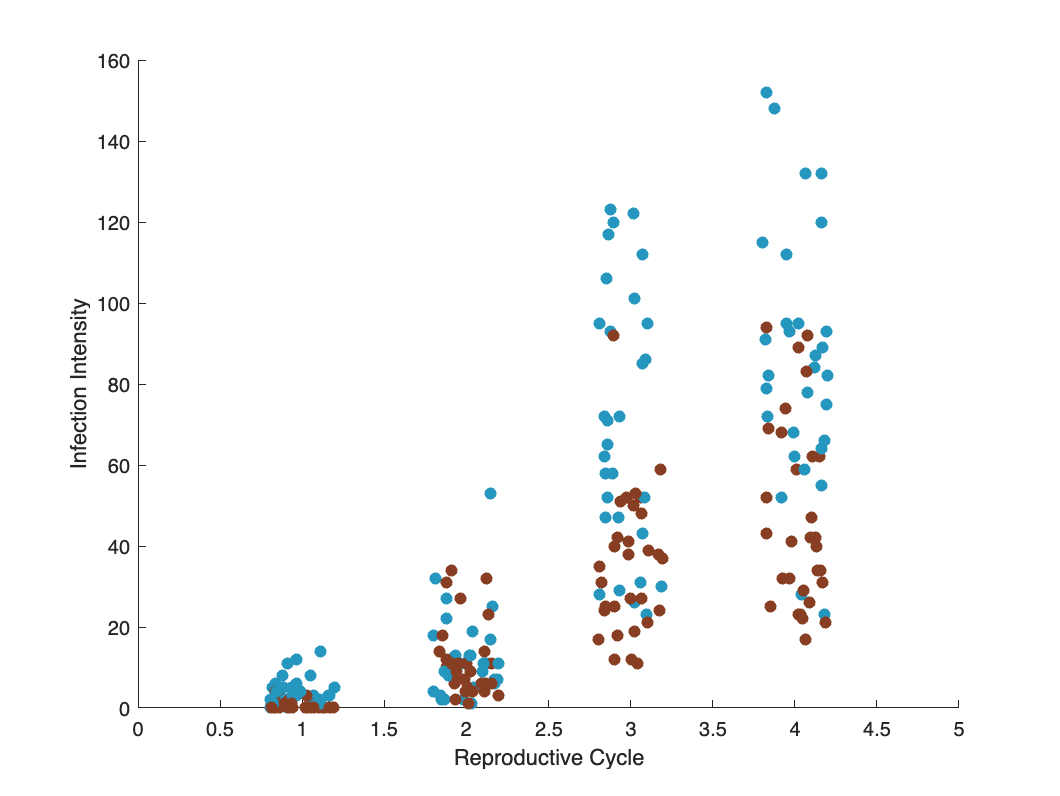

colormap(myColorMap);

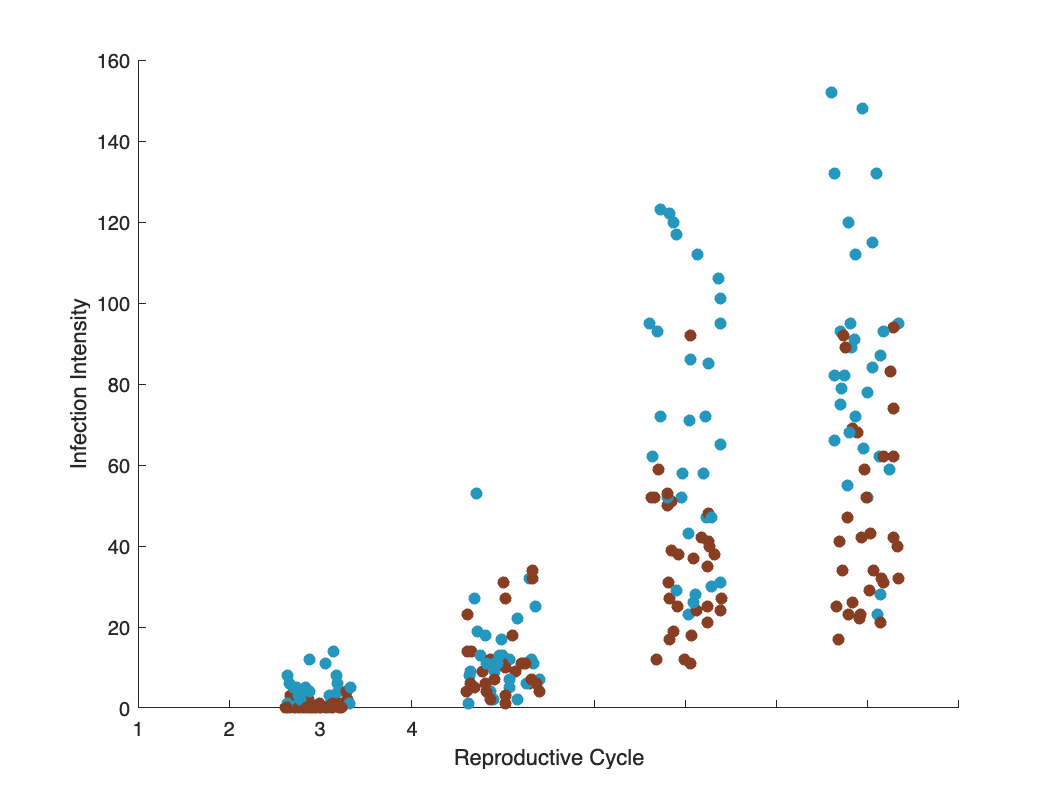

scatter(casteInf, "rep_cycle", "Infec_intensity", 'filled', 'ColorVariable', "Caste", 'jitter', 'on')
xlim([0 4.5])
xticklabels()
xlabel("Reproductive Cycle")
ylabel("Infection Intensity")